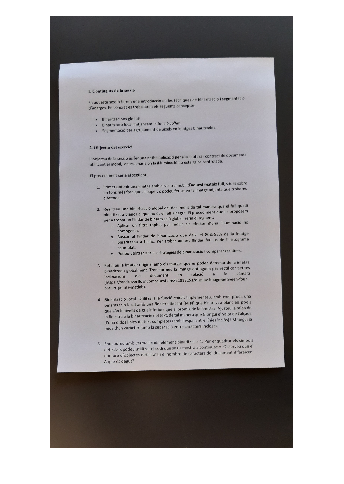

%1)Llegim la imatge a binaritzar
I = imread('20220420_124034.jpg');
I = imrotate(I,-90);
imshow(I);

I = rgb2gray(I);

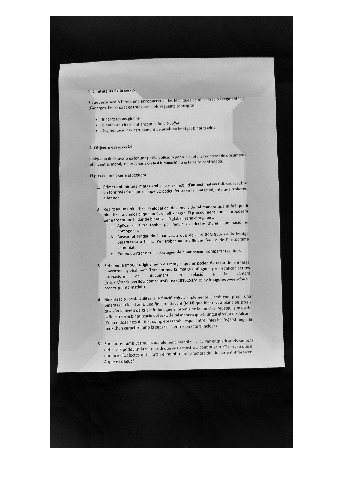

%2)Apliquem el filtre top-hat i realitzem
%una binarització del document
%se = strel('line', 110, 110);
se = strel('disk', 400);
th = imtophat(I,se);
%th = th ~= 0;
figure; imshow(th,[]);

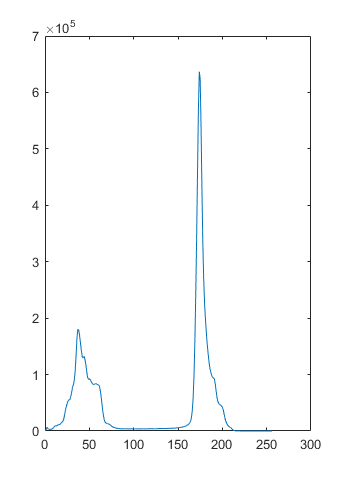

h = imhist(I); 
plot(h);

ha = cumsum(h)

ha =         1649
        8400
       13012
       16244
       19072
       21888
       24808
       28512
       33169
       40015


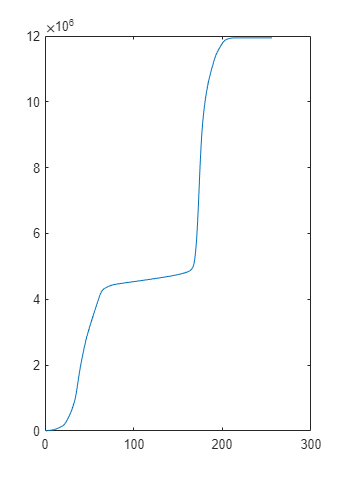

plot(ha);

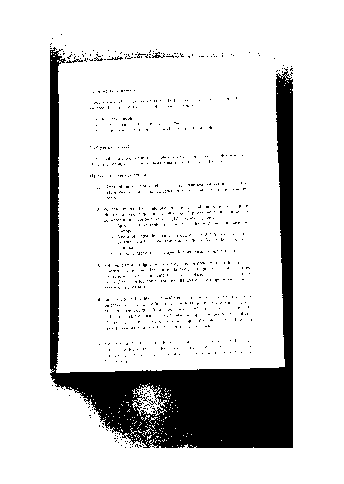

[f c]=size(I);

Area = f * c * (1 - 0.80); %% si busquem el 20-25% que ens recomana l'enunciat no ens queda un bon resutlat
r= ha > Area;
llindar = find(r,1);
BW = I > llindar; 
imshow(BW);

p_blanc = nnz(BW)/numel(BW)

p_blanc = 0.7801

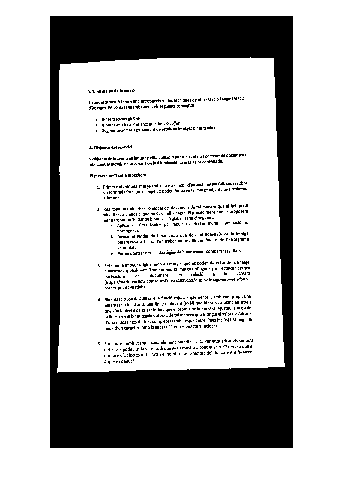


Area = f * c * (1-0.60); %% amb 0.60 es diferencia clarament el text 
r= ha > Area;
llindar = find(r,1);
BW = I > llindar; 
imshow(BW);

p_blanc = nnz(BW)/numel(BW)

p_blanc = 0.5988

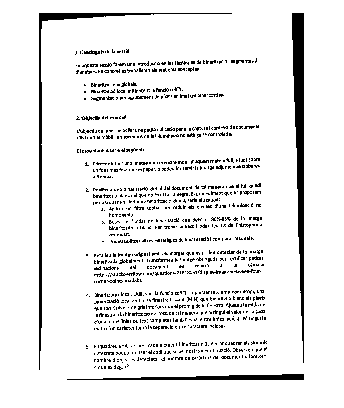

[files,columnes] = find(BW); %%retorna els elements noZero del array
primeraFilaBlanca = min(files);
ultimaFilaBlanca = max(files);
primeraColumnaBlanca = min(columnes);
ultimaColumnaBlanca = max(columnes);

Docu = BW(primeraFilaBlanca:ultimaFilaBlanca,primeraColumnaBlanca:ultimaColumnaBlanca);
local = I(primeraFilaBlanca:ultimaFilaBlanca,primeraColumnaBlanca:ultimaColumnaBlanca);

imshow(Docu);

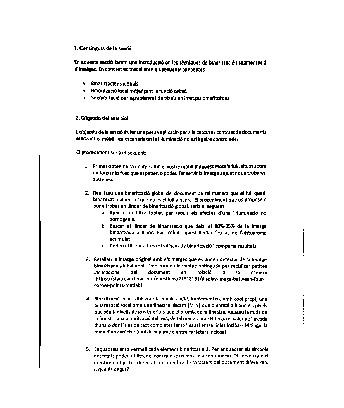

[y,x] = size(Docu);
fixedPoints=[1 1;x 1; x y; 1 y]; %(x,y) coordinate
movingPoints=[33 75;2312 4;2426 3302;1 3360];

TFORM = fitgeotrans(movingPoints,fixedPoints,'projective');
R=imref2d(size(Docu),[1 size(Docu,2)],[1 size(Docu,1)]);
globalBin=imwarp(Docu,R,TFORM,'OutputView',R);
imshow(globalBin,[]);

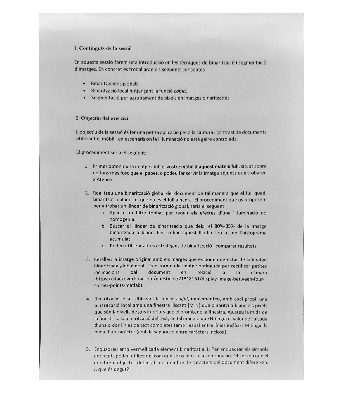


local=imwarp(local,R,TFORM,'OutputView',R);
imshow(local,[]);

De l'imatge hem extret N = 64 i M = 23, pero amb aquests nombres els resultats eren molt dolents,  per tant hem optat per una finestra molt més petita. Finalment hem agafat N = 3, M= 3 i K = 20.

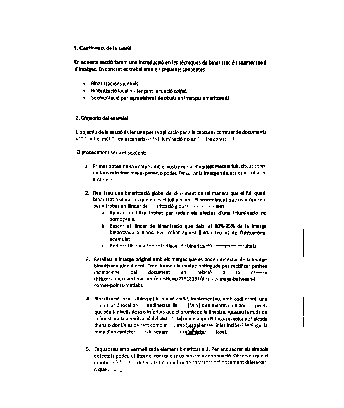

N = 3; %%extret de la imatge, 1 línia
M = 3; %%extret de la imatge, hem agafat la "a"
k = 20;
localBin = colfilt(local,[M N],"sliding", @kgris,k);
imshow(localBin,[])

Hem utilitzat com a referencia el binaritzat global, ja que el resultat final ha sigut molt més bó que amb el local.

imshow(globalBin,[]);
globalBinb = globalBin ==0; %% invertim ja que aixo conta taques blanques, no negres

labeledImage = bwconncomp(globalBinb);
numCaracters = labeledImage.NumObjects %% nombre de "caracters que detecta, es a dir taques blanques"

numCaracters = 2286

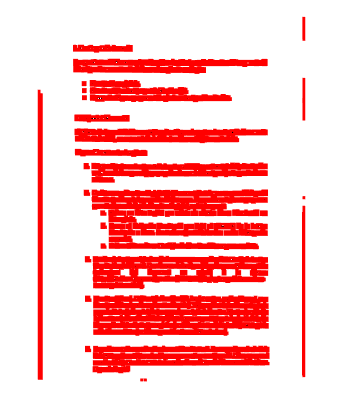

measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
thisBB = measurements(k).BoundingBox;
rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
'EdgeColor','r','LineWidth',2 )
end

Veiem que el nombre d'objectes detectats difereix del nombre de caràcters del document. Això principalment és degut a que si dues lletres es troben molt juntes, es detecten com a una sola. També, molts cops succeeix que caràcters com per exemple la i, són detectats com a dos caràcters atès que està formada per dos elements blancs.

Per elimnar les taques petites fem un imclose amb un disk molt petit, menor al signes de puntuació.

SE = strel('disk', 3);
globalBino = imclose(globalBin,SE);
imshow(globalBino,[])
globalBinb = globalBino ==0;
labeledImage = bwconncomp(globalBinb);
numCaracters = labeledImage.NumObjects %% nombre de "caracters que detecta, es a dir taques blanques"

numCaracters = 2338

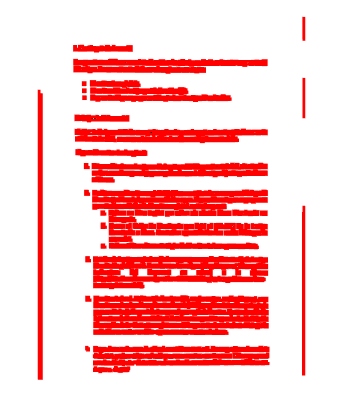

measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
thisBB = measurements(k).BoundingBox;
rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
'EdgeColor','r','LineWidth',2 )
end

Com podem veure, les uniques taques que teniem eren les dues a la part de abaix, i despres del imclose han desaparegut. El nombre de caracters ha augmentant, ja que algunes lletres ara es contem com a dos, com per exemple la m.